# Image Enhancement in the Spatial Domain 2

Created time : 2024/3/15 9:20

學號 : 109321019    姓名 : 涂价弘

## Exercise-1

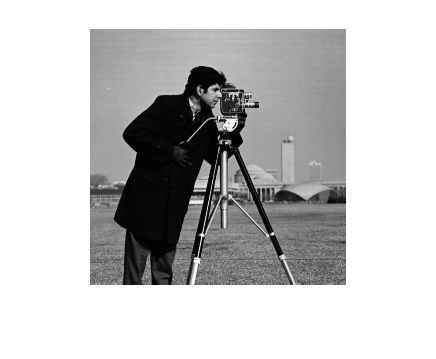

clf('reset');
img = imread('./images/2/cameraman.tif');

img = double(img);

imshow(img, [])

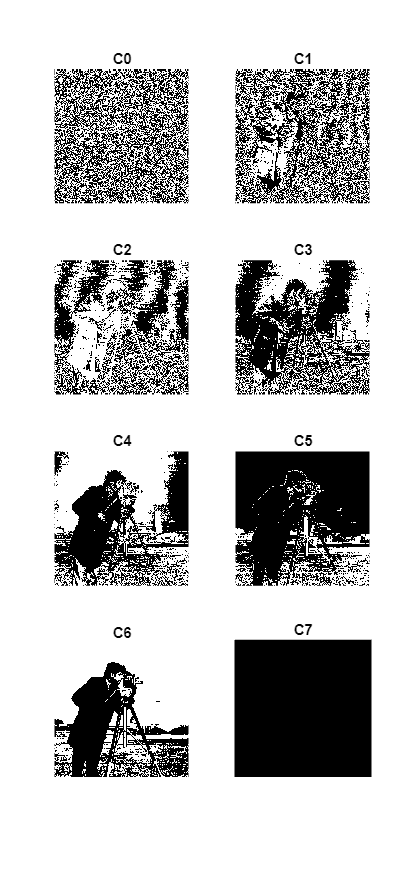


c0 = mod(img, 2);
subplot(4, 2, 1), imshow(c0, [])
title('C0')

c1 = mod(floor(img/4), 2);
subplot(4, 2, 2), imshow(c1, [])
title('C1')

c2 = mod(floor(img/8), 2);
subplot(4, 2, 3), imshow(c2, [])
title('C2')

c3 = mod(floor(img/16), 2);
subplot(4, 2, 4), imshow(c3, [])
title('C3')

c4 = mod(floor(img/32), 2);
subplot(4, 2, 5), imshow(c4, [])
title('C4')

c5 = mod(floor(img/64), 2);
subplot(4, 2, 6), imshow(c5, [])
title('C5')

c6 = mod(floor(img/128), 2);
subplot(4, 2, 7), imshow(c6, [])
title('C6')

c7 = mod(floor(img/256), 2);
subplot(4, 2, 8), imshow(c7, [])
title('C7')

truesize([110 110])

## Exercise-2

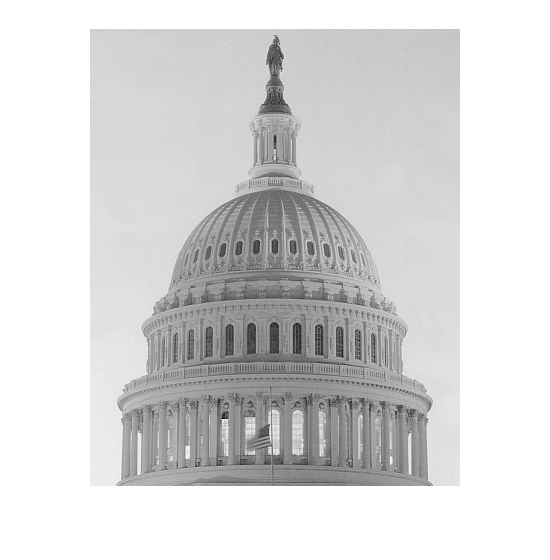

clf('reset');
img = imread('./images/3/Fig3.27(a).jpg');

imshow(img, [])

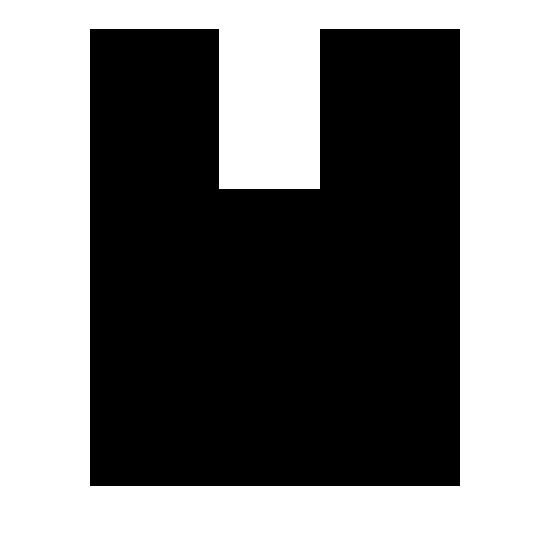


mask = zeros(size(img));
% 注意要乘上 255，不然只會有 1 bit
mask(1:160, 130:230, :) = 255 * ones(160, 101);

imshow(mask, [])

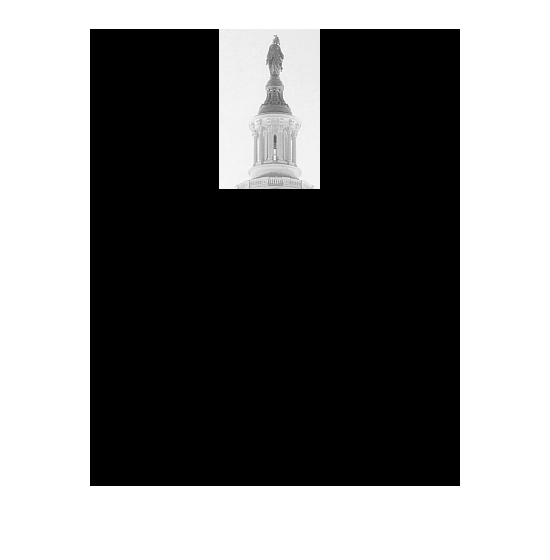


extraction = bitand(uint8(img), uint8(mask));

imshow(extraction, [])

## Exercise-3

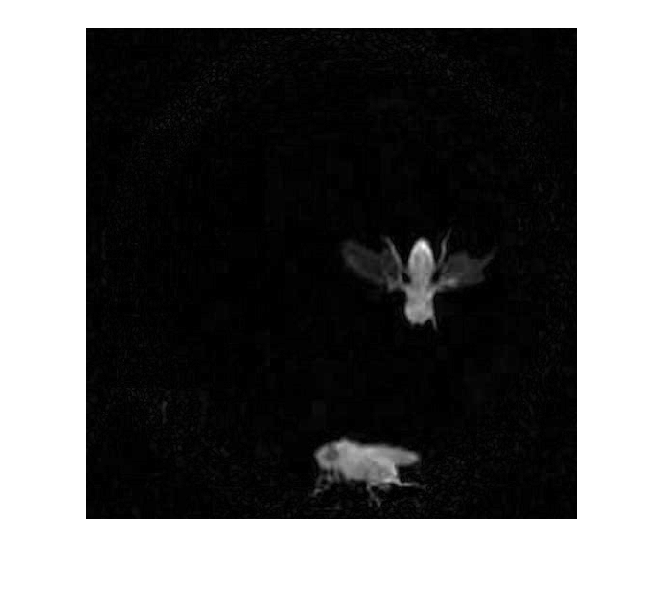

clf('reset');

video = VideoReader('./video/flyman512x512.avi');
bg = imread('./images/4/flymanBG.jpg');
bg = rgb2gray(bg);

while hasFrame(video)
    frame = readFrame(video);

    gv = rgb2gray(frame);
    diff = double(gv)- double(bg);
    substraction = abs(diff);

    imshow(substraction, [])
    break
end

## Exercise-4

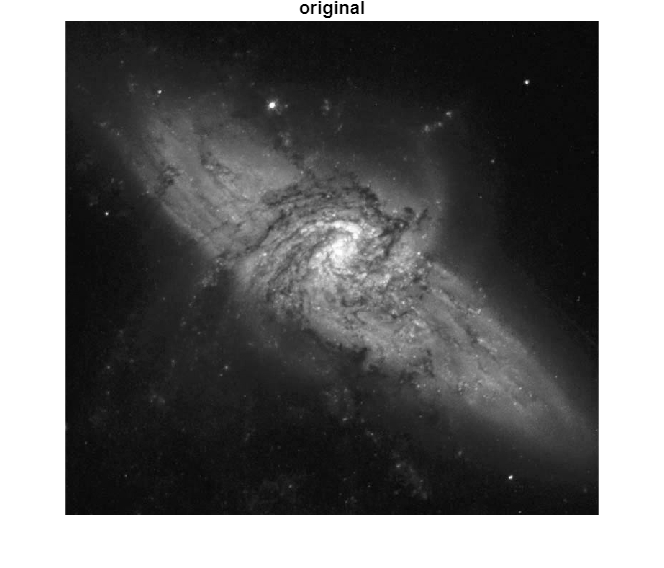

clf('reset');

img = imread('./images/3/Fig3.30(a).jpg');
img = double(img);
imshow(img, []), title('original')

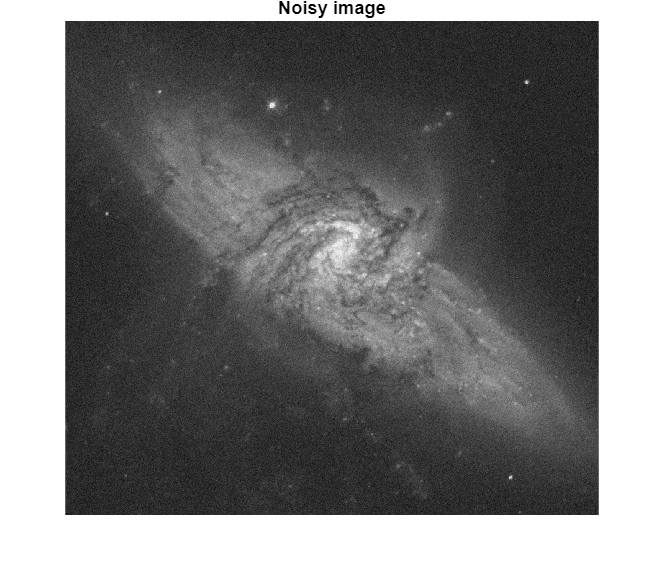


random_noises = double(10 * randn(size(img)));
noisy_img = img + random_noises;
average_img = noisy_img;

imshow(average_img, []), title('Noisy image')

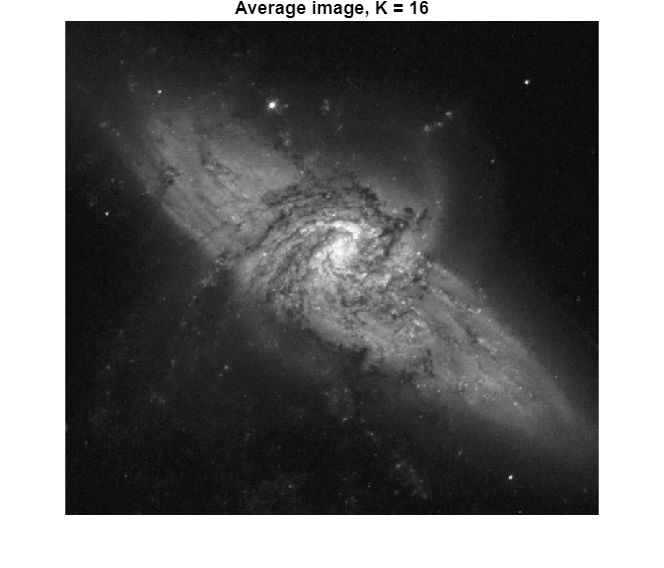


for i = 1:15
    random_noises = double(10 * randn(size(img)));
    noisy_img = img + random_noises;
    average_img = average_img + noisy_img;
end

average_img = average_img / 16;
imshow(average_img, []), title('Average image, K = 16')